addpath april_tags\
addpath brainwaves\
addpath color_masking\
addpath lidar\
addpath utils\

moj = get_mojave();

moj.setup();

Setup complete


moj.lidar.lidar_setup();

lidar_fig = figure("Name", "Lidar", "NumberTitle", "off", "Visible","on");
ang_fig = figure("Name", "Angular Brainwaves", "NumberTitle", "off", "Visible","on");
vel_fig = figure("Name", "Velocity Brainwaves", "NumberTitle","off", "Visible","on");
sonar_fig = figure("Name", "Sonar Readings", "NumberTitle","off", "Visible","on");

speeds = linspace(0, 0.9, 13);
angs = [linspace(-10, 0, 7) linspace(5, 15, 6)];

straight_wave = @(m) go_straight(m);
obstacle_wave = @(m) lidar_wave(m);
align_wave = @(m) lidar_inside_brainwave(m);
sonar_wave = @(m) sonar_brainwave(m);
path_wave = @(m) follow_color(m, @(i) beige_mask2(i));
avoid_cone = @(m) avoid_color(m, @(i) orange_2(i));
follow_blue = @(m) follow_color(m, @(i) bridge_color(i));
bridge_wave = @(m) lidar_bridge_wave(m);
follow_black = @(m) follow_color(m, @(i) depot(i));

Elapsed time is 0.000006 seconds.


distance_to_wall = 0.0098

Elapsed time is 2.405035 seconds.
Elapsed time is 2.406336 seconds.


distance_to_wall = 0

Elapsed time is 3.976621 seconds.
Elapsed time is 3.979371 seconds.


distance_to_wall = 0.0635

Elapsed time is 5.505833 seconds.
Elapsed time is 5.508035 seconds.


distance_to_wall = 0.1026

Elapsed time is 6.983512 seconds.
Elapsed time is 6.985867 seconds.


distance_to_wall = 0.2102

Elapsed time is 8.627411 seconds.
Elapsed time is 8.630516 seconds.


distance_to_wall = 0.3226

Elapsed time is 10.128457 seconds.
Elapsed time is 10.131028 seconds.


distance_to_wall = 0.3372

Elapsed time is 11.975663 seconds.
Elapsed time is 11.978013 seconds.


distance_to_wall = 0.3983

Elapsed time is 13.430256 seconds.
Elapsed time is 13.431429 seconds.


distance_to_wall = 0.3177

Elapsed time is 14.914484 seconds.
Elapsed time is 14.915897 seconds.


distance_to_wall = 0.2933

Elapsed time is 16.443908 seconds.
Elapsed time is 16.445964 seconds.


distance_to_wall = 0.1955

Elapsed time is 17.897841 seconds.
Elapsed time is 17.899062 seconds.


distance_to_wall = 0.1271

Elapsed time is 19.365736 seconds.
Elapsed time is 19.367529 seconds.


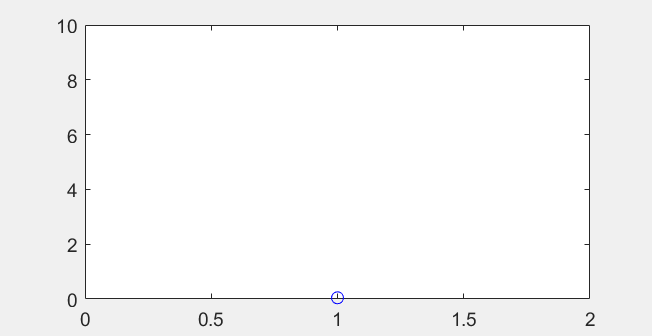

distance_to_wall = 0.0440

Elapsed time is 20.844476 seconds.
Elapsed time is 20.845735 seconds.


distance_to_wall = 0

Elapsed time is 22.211059 seconds.
Elapsed time is 22.212855 seconds.


distance_to_wall = 0

Elapsed time is 23.600321 seconds.
Elapsed time is 23.601588 seconds.


distance_to_wall = 0

Elapsed time is 24.967890 seconds.
Elapsed time is 24.969062 seconds.


distance_to_wall = 0

Elapsed time is 26.372161 seconds.
Elapsed time is 26.373323 seconds.


distance_to_wall = 0

Elapsed time is 27.767016 seconds.
Elapsed time is 27.769084 seconds.


distance_to_wall = 0

Elapsed time is 29.133308 seconds.
Elapsed time is 29.135146 seconds.


distance_to_wall = 0

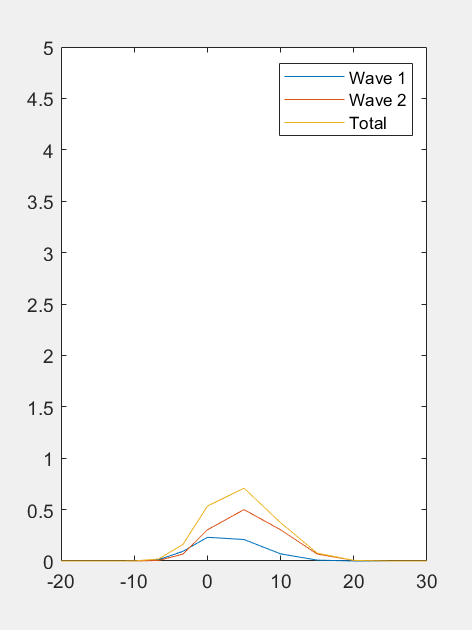

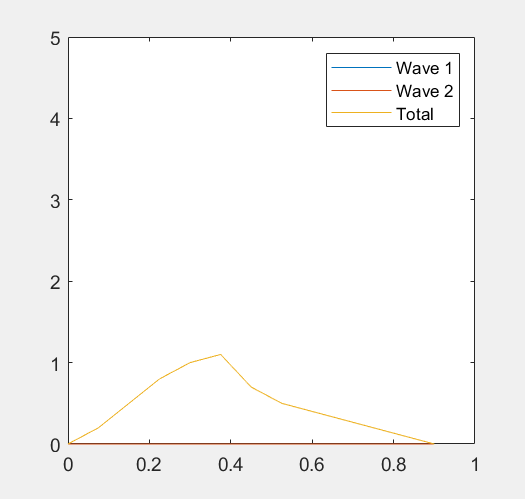

Elapsed time is 30.554878 seconds.
Elapsed time is 30.557274 seconds.


sonar_arb = arbiter({straight_wave, sonar_wave}, speeds, angs, moj);
run_robot(moj, sonar_arb, 0.5)

normal_waves = {straight_wave, path_wave};
normal_arb = arbiter(normal_waves, speeds, angs, moj);
run_robot(moj, normal_arb, 3.5);

Elapsed time is 0.000045 seconds.


Elapsed time is 1.445456 seconds.
Elapsed time is 1.448411 seconds.


Elapsed time is 2.547423 seconds.
Elapsed time is 2.548884 seconds.


Elapsed time is 3.295705 seconds.
Elapsed time is 3.297871 seconds.
Elapsed time is 4.078097 seconds.
Elapsed time is 4.079422 seconds.
Elapsed time is 4.811965 seconds.
Elapsed time is 4.813852 seconds.
Elapsed time is 5.557304 seconds.
Elapsed time is 5.559241 seconds.
Elapsed time is 6.286190 seconds.
Elapsed time is 6.288043 seconds.
Elapsed time is 7.082629 seconds.
Elapsed time is 7.084123 seconds.
Elapsed time is 7.796436 seconds.
Elapsed time is 7.798849 seconds.
Elapsed time is 8.516801 seconds.
Elapsed time is 8.518020 seconds.


Elapsed time is 9.378170 seconds.
Elapsed time is 9.379548 seconds.


Elapsed time is 10.347248 seconds.
Elapsed time is 10.349672 seconds.


Elapsed time is 11.327859 seconds.
Elapsed time is 11.329195 seconds.


Elapsed time is 12.090297 seconds.
Elapsed time is 12.091572 seconds.
Elapsed time is 12.855076 seconds.
Elapsed time is 12.857812 seconds.
Elapsed time is 13.543511 seconds.
Elapsed time is 13.545634 seconds.
Elapsed time is 14.238669 seconds.
Elapsed time is 14.241378 seconds.


Elapsed time is 15.058843 seconds.
Elapsed time is 15.060444 seconds.


Elapsed time is 15.793529 seconds.
Elapsed time is 15.795648 seconds.


Elapsed time is 16.666858 seconds.
Elapsed time is 16.668975 seconds.
Elapsed time is 17.379506 seconds.
Elapsed time is 17.380728 seconds.


Elapsed time is 18.160357 seconds.
Elapsed time is 18.161923 seconds.
Elapsed time is 18.910744 seconds.
Elapsed time is 18.912229 seconds.


Elapsed time is 19.615428 seconds.
Elapsed time is 19.617392 seconds.


Elapsed time is 20.407660 seconds.
Elapsed time is 20.408974 seconds.


Elapsed time is 21.237922 seconds.
Elapsed time is 21.239148 seconds.


Elapsed time is 22.013199 seconds.
Elapsed time is 22.015265 seconds.


Elapsed time is 22.770270 seconds.
Elapsed time is 22.772142 seconds.


Elapsed time is 23.736082 seconds.
Elapsed time is 23.737537 seconds.


Elapsed time is 24.458682 seconds.
Elapsed time is 24.459929 seconds.


Elapsed time is 25.188598 seconds.
Elapsed time is 25.189897 seconds.


Elapsed time is 26.181634 seconds.
Elapsed time is 26.183415 seconds.


Elapsed time is 26.954533 seconds.
Elapsed time is 26.956551 seconds.


Elapsed time is 27.810191 seconds.
Elapsed time is 27.811419 seconds.
Elapsed time is 28.592001 seconds.
Elapsed time is 28.593236 seconds.


Elapsed time is 29.325436 seconds.
Elapsed time is 29.327143 seconds.


Elapsed time is 30.105733 seconds.
Elapsed time is 30.107924 seconds.


Elapsed time is 30.807838 seconds.
Elapsed time is 30.809117 seconds.


Elapsed time is 31.513142 seconds.
Elapsed time is 31.514962 seconds.


Elapsed time is 32.231307 seconds.
Elapsed time is 32.233424 seconds.


Elapsed time is 32.933870 seconds.
Elapsed time is 32.935301 seconds.


Elapsed time is 33.651501 seconds.
Elapsed time is 33.653275 seconds.


Elapsed time is 34.439663 seconds.
Elapsed time is 34.441448 seconds.


Elapsed time is 35.217050 seconds.
Elapsed time is 35.218822 seconds.


Elapsed time is 35.995956 seconds.
Elapsed time is 35.997169 seconds.
Elapsed time is 36.727648 seconds.
Elapsed time is 36.730581 seconds.
Elapsed time is 37.446317 seconds.
Elapsed time is 37.449821 seconds.


Elapsed time is 38.207657 seconds.
Elapsed time is 38.208859 seconds.
Elapsed time is 38.988641 seconds.
Elapsed time is 38.989942 seconds.


Elapsed time is 39.706870 seconds.
Elapsed time is 39.708618 seconds.


Elapsed time is 40.533912 seconds.
Elapsed time is 40.535126 seconds.


Elapsed time is 41.342038 seconds.
Elapsed time is 41.343278 seconds.


Elapsed time is 42.122824 seconds.
Elapsed time is 42.124069 seconds.


Elapsed time is 43.178064 seconds.
Elapsed time is 43.179865 seconds.


Elapsed time is 44.320252 seconds.
Elapsed time is 44.322572 seconds.


Elapsed time is 45.459210 seconds.
Elapsed time is 45.461141 seconds.


Elapsed time is 46.492639 seconds.
Elapsed time is 46.493936 seconds.


Elapsed time is 47.238623 seconds.
Elapsed time is 47.240571 seconds.


Elapsed time is 48.018825 seconds.
Elapsed time is 48.020109 seconds.


Elapsed time is 48.908479 seconds.
Elapsed time is 48.909754 seconds.


Elapsed time is 49.691760 seconds.
Elapsed time is 49.693368 seconds.


Elapsed time is 50.706386 seconds.
Elapsed time is 50.707739 seconds.
Elapsed time is 51.465676 seconds.
Elapsed time is 51.466890 seconds.


Elapsed time is 52.295667 seconds.
Elapsed time is 52.298130 seconds.


Elapsed time is 53.043330 seconds.
Elapsed time is 53.045148 seconds.


Elapsed time is 53.826210 seconds.
Elapsed time is 53.828246 seconds.


Elapsed time is 54.670541 seconds.
Elapsed time is 54.672226 seconds.


Elapsed time is 55.472869 seconds.
Elapsed time is 55.475059 seconds.


Elapsed time is 56.277687 seconds.
Elapsed time is 56.279513 seconds.


Elapsed time is 57.079165 seconds.
Elapsed time is 57.080622 seconds.


Elapsed time is 57.894800 seconds.
Elapsed time is 57.896257 seconds.


Elapsed time is 58.692676 seconds.
Elapsed time is 58.694871 seconds.


Elapsed time is 59.525887 seconds.
Elapsed time is 59.528277 seconds.


Elapsed time is 60.571829 seconds.
Elapsed time is 60.574901 seconds.


Elapsed time is 61.687849 seconds.
Elapsed time is 61.689973 seconds.


Elapsed time is 62.858840 seconds.
Elapsed time is 62.861660 seconds.


Elapsed time is 63.837794 seconds.
Elapsed time is 63.839033 seconds.


Elapsed time is 64.650218 seconds.
Elapsed time is 64.651416 seconds.


Elapsed time is 65.413364 seconds.
Elapsed time is 65.414983 seconds.


Elapsed time is 66.149614 seconds.
Elapsed time is 66.151368 seconds.


Elapsed time is 67.223912 seconds.
Elapsed time is 67.225169 seconds.


Elapsed time is 67.981939 seconds.
Elapsed time is 67.983692 seconds.


Elapsed time is 68.795484 seconds.
Elapsed time is 68.797476 seconds.


Elapsed time is 69.575816 seconds.
Elapsed time is 69.578260 seconds.


Elapsed time is 70.389720 seconds.
Elapsed time is 70.391249 seconds.


Elapsed time is 71.155219 seconds.
Elapsed time is 71.156979 seconds.


Elapsed time is 71.958445 seconds.
Elapsed time is 71.960320 seconds.


Elapsed time is 72.817946 seconds.
Elapsed time is 72.820522 seconds.


Elapsed time is 73.849513 seconds.
Elapsed time is 73.851175 seconds.


Elapsed time is 74.645507 seconds.
Elapsed time is 74.647316 seconds.


Elapsed time is 75.613979 seconds.
Elapsed time is 75.615228 seconds.


Elapsed time is 76.459819 seconds.
Elapsed time is 76.461074 seconds.


Elapsed time is 77.471310 seconds.
Elapsed time is 77.472617 seconds.


Elapsed time is 78.236735 seconds.
Elapsed time is 78.238407 seconds.


Elapsed time is 78.936216 seconds.
Elapsed time is 78.937959 seconds.


Elapsed time is 79.654601 seconds.
Elapsed time is 79.656439 seconds.


Elapsed time is 80.421037 seconds.
Elapsed time is 80.422966 seconds.


Elapsed time is 81.275986 seconds.
Elapsed time is 81.277891 seconds.


Elapsed time is 82.039642 seconds.
Elapsed time is 82.040907 seconds.


Elapsed time is 82.762230 seconds.
Elapsed time is 82.764465 seconds.


Elapsed time is 83.609987 seconds.
Elapsed time is 83.611994 seconds.


Elapsed time is 84.466514 seconds.
Elapsed time is 84.468351 seconds.


Elapsed time is 85.435240 seconds.
Elapsed time is 85.438171 seconds.


Elapsed time is 86.239528 seconds.
Elapsed time is 86.241033 seconds.


Elapsed time is 87.050923 seconds.
Elapsed time is 87.053010 seconds.


Elapsed time is 87.857745 seconds.
Elapsed time is 87.859904 seconds.


Elapsed time is 88.637997 seconds.
Elapsed time is 88.640308 seconds.


Elapsed time is 89.430910 seconds.
Elapsed time is 89.432798 seconds.


Elapsed time is 90.251113 seconds.
Elapsed time is 90.252558 seconds.


Elapsed time is 91.009327 seconds.
Elapsed time is 91.012332 seconds.
Elapsed time is 91.770055 seconds.
Elapsed time is 91.771564 seconds.


Elapsed time is 92.640599 seconds.
Elapsed time is 92.642013 seconds.


Elapsed time is 93.545400 seconds.
Elapsed time is 93.547813 seconds.


Elapsed time is 94.508404 seconds.
Elapsed time is 94.511404 seconds.


Elapsed time is 95.405315 seconds.
Elapsed time is 95.407869 seconds.


Elapsed time is 96.439194 seconds.
Elapsed time is 96.441128 seconds.


Elapsed time is 97.388654 seconds.
Elapsed time is 97.390890 seconds.


Elapsed time is 98.248035 seconds.
Elapsed time is 98.249213 seconds.


Elapsed time is 99.133286 seconds.
Elapsed time is 99.135575 seconds.


Elapsed time is 99.926423 seconds.
Elapsed time is 99.927975 seconds.


Elapsed time is 100.722048 seconds.
Elapsed time is 100.723730 seconds.


Elapsed time is 101.500325 seconds.
Elapsed time is 101.501593 seconds.


Elapsed time is 102.336798 seconds.
Elapsed time is 102.338042 seconds.


Elapsed time is 103.239423 seconds.
Elapsed time is 103.241086 seconds.


Elapsed time is 104.076923 seconds.
Elapsed time is 104.078658 seconds.


Elapsed time is 105.351599 seconds.
Elapsed time is 105.353953 seconds.


Elapsed time is 106.223690 seconds.
Elapsed time is 106.225103 seconds.


Elapsed time is 107.085025 seconds.
Elapsed time is 107.087879 seconds.
Elapsed time is 107.888827 seconds.
Elapsed time is 107.890268 seconds.


Elapsed time is 108.681955 seconds.
Elapsed time is 108.683743 seconds.


Elapsed time is 109.474951 seconds.
Elapsed time is 109.476900 seconds.


Elapsed time is 110.280952 seconds.
Elapsed time is 110.282629 seconds.


Elapsed time is 111.092960 seconds.
Elapsed time is 111.094225 seconds.


Elapsed time is 111.933568 seconds.
Elapsed time is 111.934856 seconds.


Elapsed time is 112.784223 seconds.
Elapsed time is 112.785446 seconds.


Elapsed time is 113.558319 seconds.
Elapsed time is 113.560022 seconds.


Elapsed time is 114.381993 seconds.
Elapsed time is 114.383202 seconds.


Elapsed time is 115.238770 seconds.
Elapsed time is 115.240407 seconds.


Elapsed time is 116.005510 seconds.
Elapsed time is 116.009043 seconds.


Elapsed time is 116.808197 seconds.
Elapsed time is 116.809714 seconds.


Elapsed time is 117.606659 seconds.
Elapsed time is 117.608366 seconds.


Elapsed time is 118.423716 seconds.
Elapsed time is 118.424898 seconds.


Elapsed time is 119.369709 seconds.
Elapsed time is 119.371938 seconds.


Elapsed time is 120.132857 seconds.
Elapsed time is 120.134080 seconds.


Elapsed time is 120.955480 seconds.
Elapsed time is 120.957048 seconds.


Elapsed time is 121.798021 seconds.
Elapsed time is 121.799351 seconds.


Elapsed time is 122.638925 seconds.
Elapsed time is 122.640889 seconds.


bridge_waves = {straight_wave, follow_blue, bridge_wave};
bridge_arb = arbiter(bridge_waves, speeds, angs, moj);
run_robot(moj, bridge_arb, @(m) until_no_color(m, @(i) blue_mask(i), 0.1));

run_robot(moj, normal_arb, @(m) until_tag_seen(m, 0, 5000));

park_waves = {straight_wave, follow_black, depot_wave, obstacle_wave};
park_arb = arbiter(park_waves, speeds, angs, moj);
run_robot(moj, park_arb, @(m) until_tag_seen(m, 0, 500));

function done = until_color(moj, mask_func, min_percent)
    img = moj.sense_cam();
    mask = mask_func(img);
    mask = mask(800:1200, 1:end);
    amt_color = sum(mask(:));
    num_pixels = size(mask, 1) * size(mask, 2);
    done = amt_color / num_pixels > min_percent;
end

function done = until_no_color(moj, mask_func, max_percent)
    img = moj.sense_cam();
    mask = mask_func(img);
    mask = mask(800:1200, 1:end);
    amt_color = sum(mask(:));
    num_pixels = size(mask, 1) * size(mask, 2);
    done = amt_color / num_pixels < max_percent;
end

function done = until_tag_seen(moj, tag_id, min_dist)
    done = false;
    tags = moj.find_april_tags();
    if isempty(tags)
        return
    end

    ids = zeros(size(tags));
    for i = 1:length(tags)
        ids(i) = tags(i).id;
    end

    if ~any(ids == tag_id)
        return
    end

    tag = tags(ids == tag_id);
    if norm(tag.pose.Translation) < min_dist
        done = true;
    end
end